%Euler Explicit Example
clear all;
clc;

% write a function for the ODE that we are trying to solve
dydx = @(x,y)x.^2*y

dydx = function_handle with value:
    @(x,y)x.^2.*y


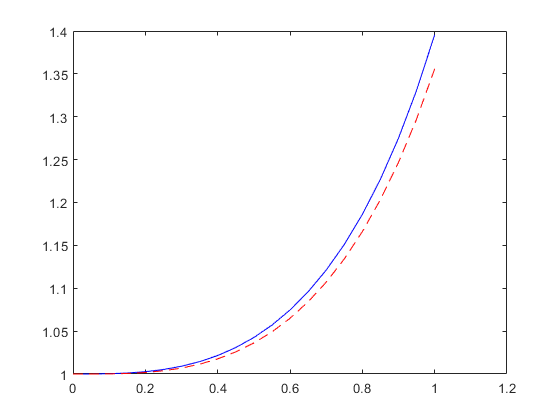


% set the initial condition
x0 = 0.0;
y0 = 1.0;

% set the domain size for the integration
xf = 1.0;

% set the integration step size
dx = 0.05;
NoOfSteps = 20;

% Carry out Euler Explicit Method to numerically integrate
% initialize
x = zeros(NoOfSteps+1,1);
y = zeros(NoOfSteps+1,1);
x(1) = x0;
y(1) = y0;

for i = 1:NoOfSteps
    % euler explicit
    y(i+1) = y(i) + dx*dydx(x(i),y(i));
    x(i+1) = x(i) + dx;
end

% Create the exact/analytical solution
% Initialize

for i = 1:NoOfSteps+1
    % exact solution is y = exp(x^3/3)
    ya(i) = exp((x(i).^3)/3);
end

% plot the numerical and exact solutions
plot(x,ya,'b-',x,y,'r--')